# **第九章 循环神经网络与长短时记忆神经网络**

**版权申明：**

- **本文件由山西大学复杂系统研究所郁磊副教授开发完成。未取得授权的情况下，请勿私自传播，传播形式包括但不限于：拷贝、传输、打印等。授权相关事宜请通过电子邮件沟通联系（Email: yulei@sxu.edu.cn）。**

- **本文件在开发过程中得到了迈斯沃克软件（北京）有限公司与教育部产学合作协同育人项目的支持。**

## **9.1 循环神经网络简介**

        以卷积神经网络为代表的深度神经网络模型在图像处理、目标检测和图像分割等领域取得了广泛的应用，然而在时间序列类数据（譬如：气象预报、自然语言处理等）的建模中应用效果却不甚理想。这与数据的特点直接相关，因为在传统的机器学习中，都假设样本之间是独立同分布的，模型在学习一个样本的过程中，不会将其与之前学过的样本关联起来，而这个假设在时间序列类数据中是不成立的，因为从时间序列中抽取出的样本之间必然是存在相关性的。为了让模型能够记住学习过的每个样本，需要在前向型神经网络的基础上增加“记忆单元”，即用存储器的方式将隐含层神经元的状态记录下来，于是，循环神经网络（Recurrent Neural Network, RNN）模型应运而生。

        循环神经网络按时间步展开后，其拓扑结构如图1所示。与前向型神经网络不同的地方在于，对于每个时间步而言，当前时刻的输出除了与当前时刻的输入有关外，还与前一个时刻记忆单元中存储的内容有关，即实现了记忆的功能。

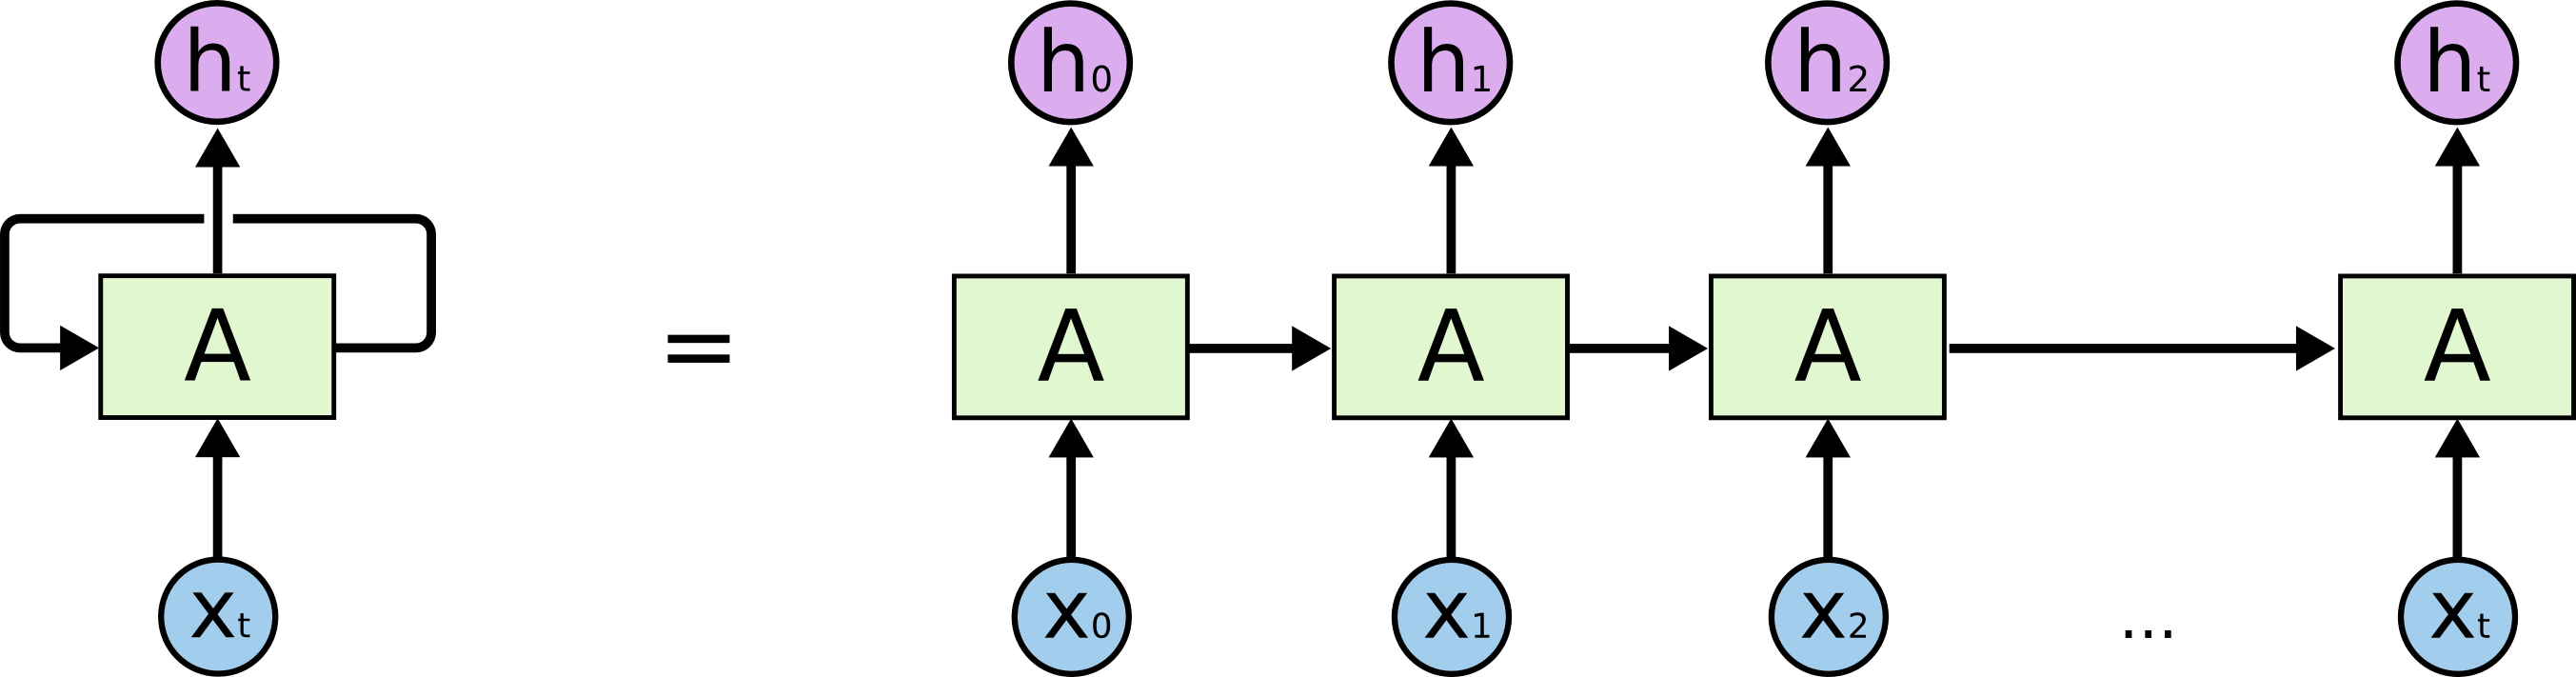

图1 循环神经网络拓扑结构示意图

        RNN模型的前向传播过程主要包括下面几个步骤：

- **输入处理：**在每个时间步，RNN接收两个输入：当前时间步的输入和上一个时间步的隐藏状态。

- **隐藏状态更新：**根据当前输入和上一时间步的隐藏状态，通过循环单元计算新的隐藏状态。这个过程允许网络“记住”并利用过去的信息。

- **输出生成：**根据当前时间步的隐藏状态生成输出。对于不同的任务，输出可以是分类（如在语言模型中的下一个单词），或者是对连续值的预测（如在时间序列分析中的未来值）。

        RNN模型的训练算法具体步骤如下：

- **初始化：**设置初始隐藏状态（通常为零向量）和网络参数。

- **前向传播：**(1) 对于序列中的每个时间步，计算当前时间步的隐藏状态。这通常通过一个激活函数（如tanh）来完成，函数将当前输入和上一时间步的隐藏状态作为输入。(2) 生成输出，这可能涉及额外的处理，例如通过一个全连接层。

- **损失计算：**根据实际输出和期望输出计算损失函数，通常是交叉熵损失（对于分类任务）或均方误差（对于回归任务）。

- **反向传播与优化：**使用反向传播算法（如梯度下降）计算梯度，并更新网络的权重。在这个过程中，梯度会沿时间步反向传播，这称为“通过时间的反向传播”（Backpropagation Through Time, BPTT）。

- **迭代过程：**重复以上步骤，直到满足停止条件，如达到预定的迭代次数或损失足够小。

        从上面的分析中可以发现，从第一个时刻开始，RNN期望能够记住所有之前时刻的信息，这个想法是好的，但是在具体实现的时候，很容易出现“梯度消失”问题。如图2所示，随着时间步的增加，会出现连续的矩阵乘法，梯度可能随时间变得非常小（消失），这使得训练变得困难，导致难以捕获长期依赖性（即当当前输出依赖于序列中很远的过去输入时）。

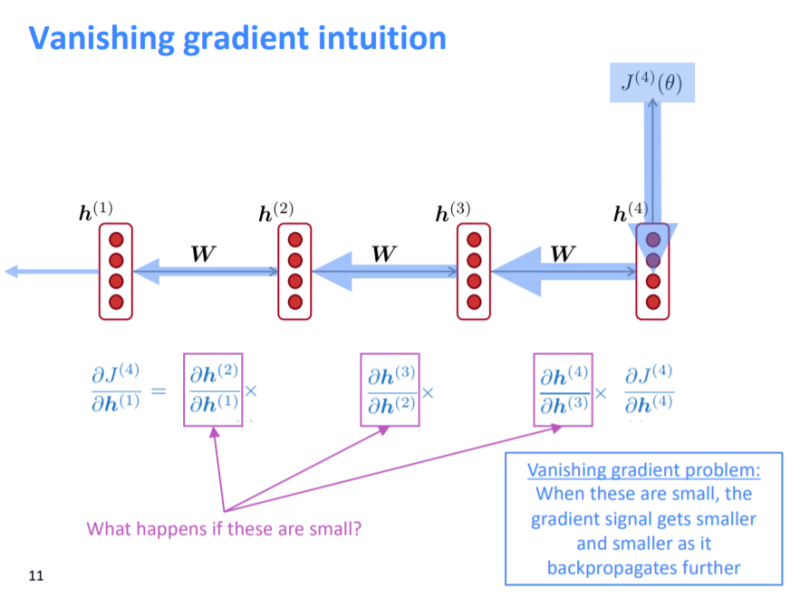

图2 梯度消失问题示意图

## **9.2 长短时记忆神经网络简介**

        为了解决RNN存在的梯度消失问题，Jürgen Schmidhuber等人于1997年提出了长短期记忆（Long Short-Term Memory, LSTM）神经网络模型。LSTM通过其独特的结构，有效解决了标准RNN在处理长期依赖关系时面临的挑战，使其能够有效地学习长期依赖信息。

        与RNN最大的不同之处在于，LSTM神经网络中设计了一个如图3所示的LSTM单元，为了详细了解其工作过程，需要先阐明几个基本概念：

- **单元状态（Cell State）：**LSTM的核心部分是单元状态，它类似于传送带，整个链条上几乎不变地运行，只有一些小的线性交互。这使得网络能够相对容易地将信息传递下去。

- **门控制机制：**LSTM通过结构化的门控制机制来控制单元状态，包括遗忘门（forget gate）、输入门（input gate）和输出门（output gate）。

- **遗忘门：**决定从单元状态中丢弃什么信息。这是通过一个sigmoid层来实现的，它查看当前输入和上一个隐藏状态，输出一个0到1之间的数值给每个在单元状态中的数字，1表示“完全保留”，0表示“完全遗忘”。

- **输入门：**更新单元状态的新信息。首先，一个sigmoid层决定哪些值我们将要更新。接着，一个tanh层创建一个新的候选值向量，它可以被加到状态中。然后，我们将这两个信息相乘，决定最终更新状态的方式。

- **输出门：**基于单元状态决定输出什么值，但会是一个过滤过的版本。首先，我们运行一个sigmoid层来决定单元状态的哪些部分将输出出去。然后，我们将单元状态通过tanh（得到一个值在-1到1之间的输出）并将其与sigmoid门的输出相乘，以便我们只输出我们想要的部分。

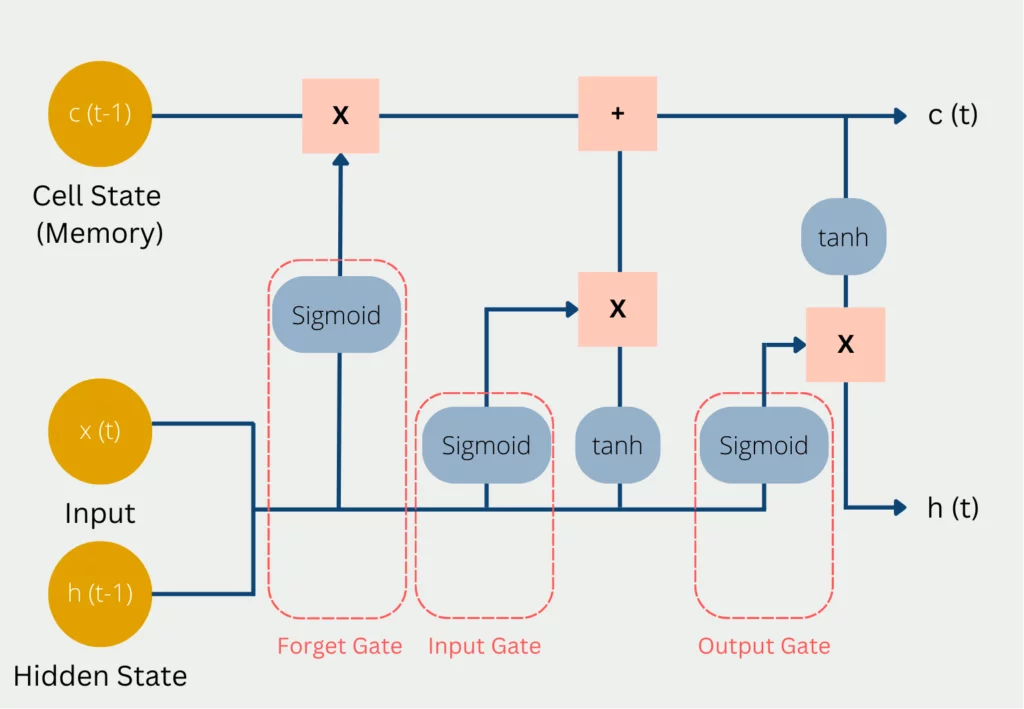

图3 LSTM单元的内部结构示意图

        LSTM神经网络的训练过程主要包括下面几个步骤：

- **初始化：**设置初始隐藏状态和单元状态，通常为零向量。

- **前向传播：**对于序列中的每个时间步，计算四个主要的组件：遗忘门、输入门、单元状态更新和输出门。同时，更新隐藏状态和单元状态。

- **损失计算：**根据实际输出和期望输出计算损失函数。

- **反向传播与优化：**使用反向传播算法（如梯度下降）计算梯度，并更新网络的权重。在这个过程中，梯度会沿时间步反向传播，这称为“通过时间的反向传播”（Backpropagation Through Time, BPTT）。

- **迭代过程：**重复以上步骤，直到满足停止条件，如达到预定的迭代次数或损失足够小。

        LSTM网络通过其独特的结构有效地克服了标准RNN在处理长序列数据时遇到的梯度消失问题，使其能够学习和保持长期依赖关系。这使得LSTM在各种涉及序列数据的任务中，如语言建模、文本生成、语音识别等领域非常有效。

## **9.3 案例1：基于LSTM神经网络的水痘患病人数预测**

- **导入数据**

        MATLAB内置的数据集chickenpox_dataset中包含了一共498个月的水痘患病人数。

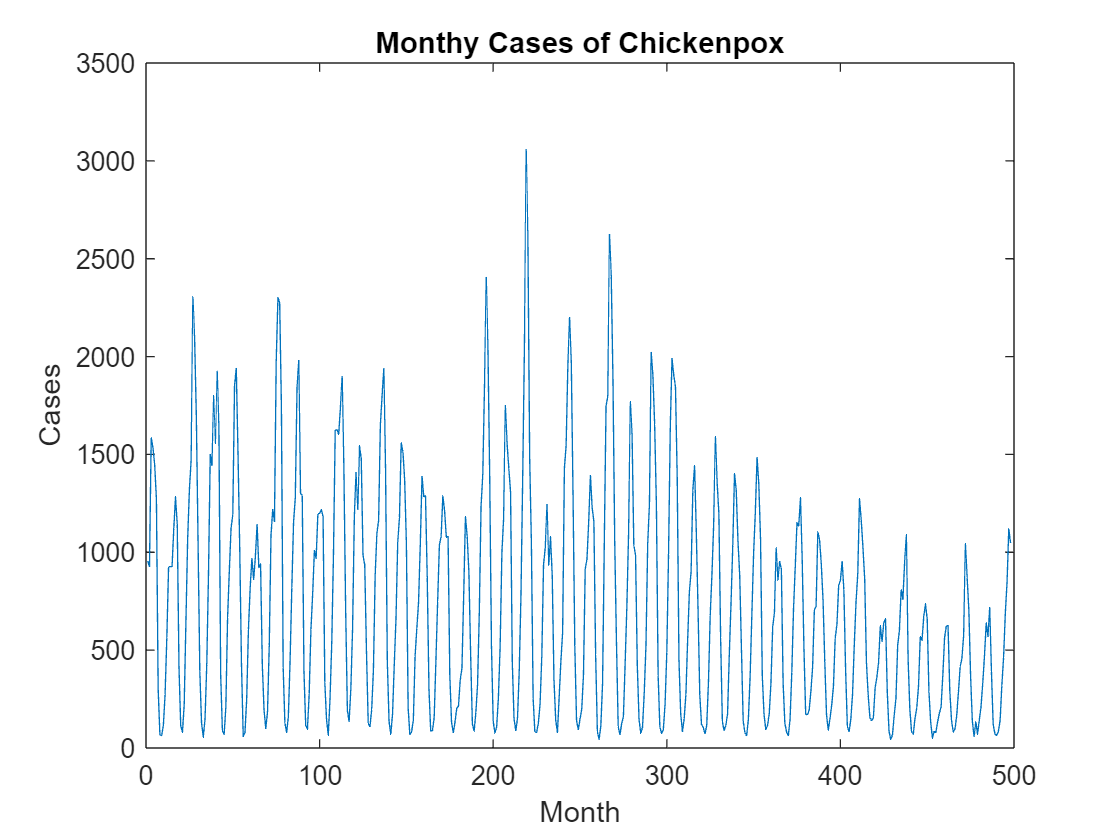

data = chickenpox_dataset;
data = [data{:}];

% 绘图
figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthy Cases of Chickenpox")

- **划分训练集与测试集**

        在对时间序列数据进行划分时，注意不能使用随机划分的方法，这里我们选取前90%的数据作为训练集，剩余的10%的数据作为测试集。此外，在这个例子里，我们拟构建的模型是利用前两个月的水痘患病人数预测当前这个月的水痘患病人数。

numTimeStepsTrain = floor(0.9*numel(data));
XTrain = [data(1:numTimeStepsTrain-1);data(2:numTimeStepsTrain)];
YTrain = data(3:numTimeStepsTrain+1);
XTest = [data(numTimeStepsTrain:end-2);data(numTimeStepsTrain+1:end-1)];
YTest = data(numTimeStepsTrain+2:end);

- **数据标准化**

mu_x = mean(XTrain,2);
sig_x = std(XTrain');
sig_x = sig_x';
XTrain = (XTrain - mu_x) ./ sig_x;

mu_y = mean(YTrain);
sig_y = std(YTrain);
YTrain = (YTrain - mu_y) ./ sig_y;

XTest = (XTest - mu_x) ./ sig_x;

- **定义LSTM神经网络拓扑结构**

inputSize = 2;
numResponses = 1;
numHiddenUnits = 100;

layers = [sequenceInputLayer(inputSize)
          lstmLayer(numHiddenUnits)
          fullyConnectedLayer(numResponses)
          regressionLayer];  

- **设置训练参数**

opts = trainingOptions('adam', ...
                       'MaxEpochs',500, ...
                       'GradientThreshold',1, ...
                       'InitialLearnRate',0.005, ...
                       'LearnRateSchedule','piecewise', ...
                       'LearnRateDropPeriod',125, ...
                       'LearnRateDropFactor',0.2, ...
                       'Verbose',0, ...
                       'Plots','training-progress');

- **训练LSTM神经网络**

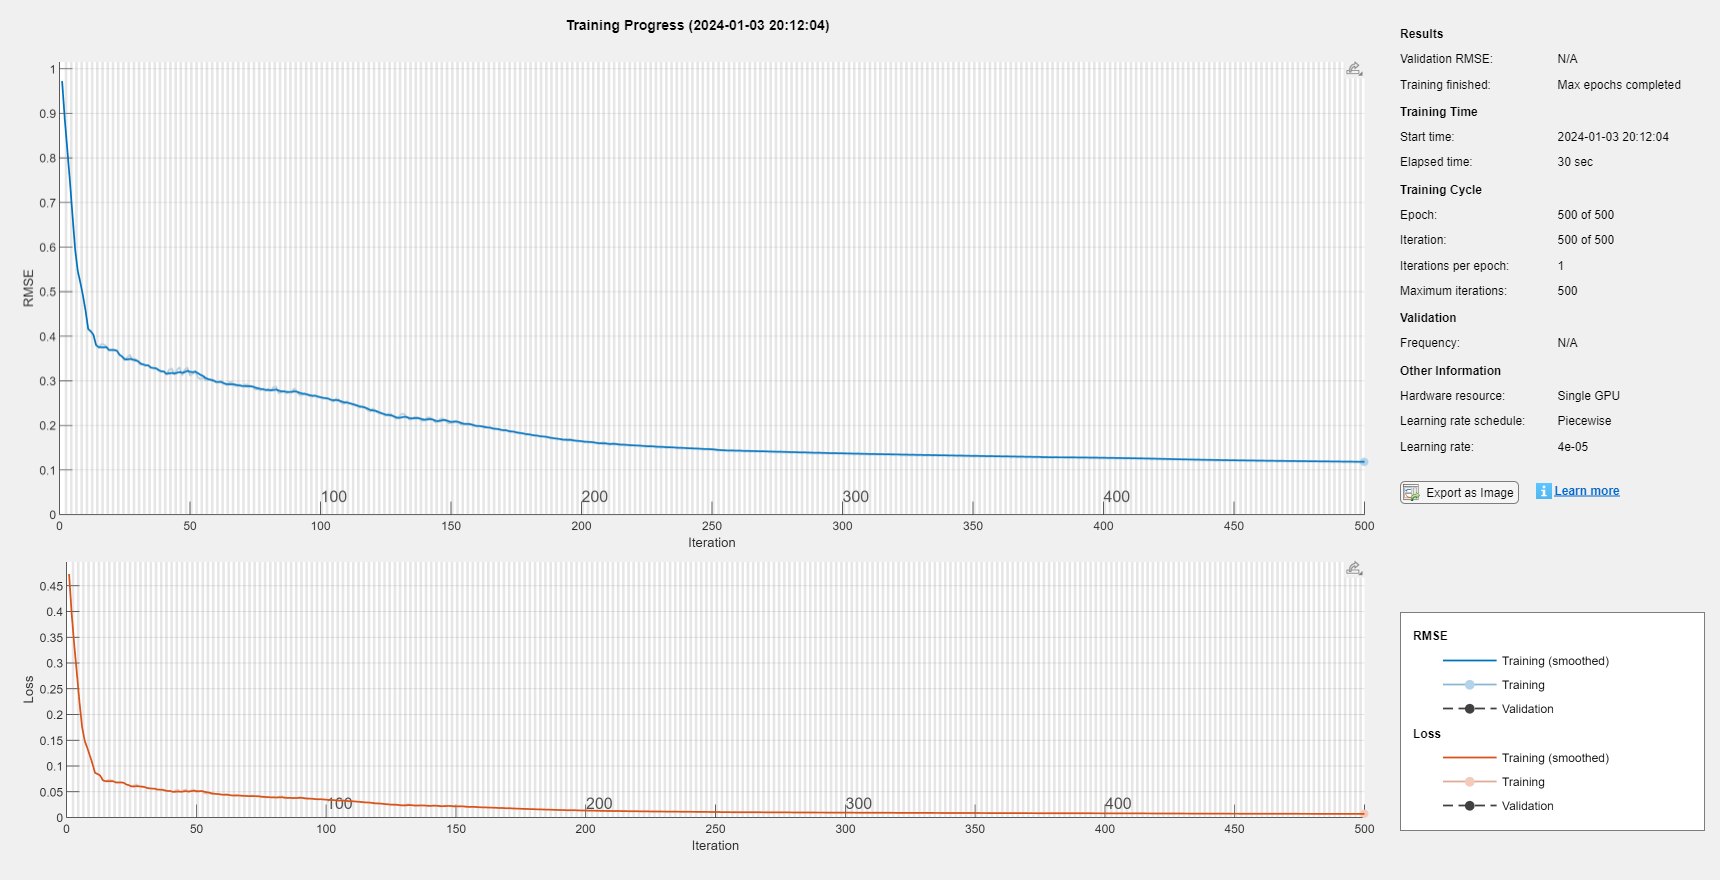

net = trainNetwork(XTrain,YTrain,layers,opts);

- **模型预测**

net = predictAndUpdateState(net,XTrain);
[net,YPred(1)] = predictAndUpdateState(net,[YTrain(end-1);YTrain(end)]);
[net,YPred(2)] = predictAndUpdateState(net,[YTrain(end);YPred(1)]);

% 滚动预测
numTimeStepsTest = size(XTest,2);
for i = 3:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,[YPred(i-2);YPred(i-1)]);
end

- **反标准化**

YPred = sig_y*YPred + mu_y;

- **计算均方根误差**

rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
244.8298

- **绘图**

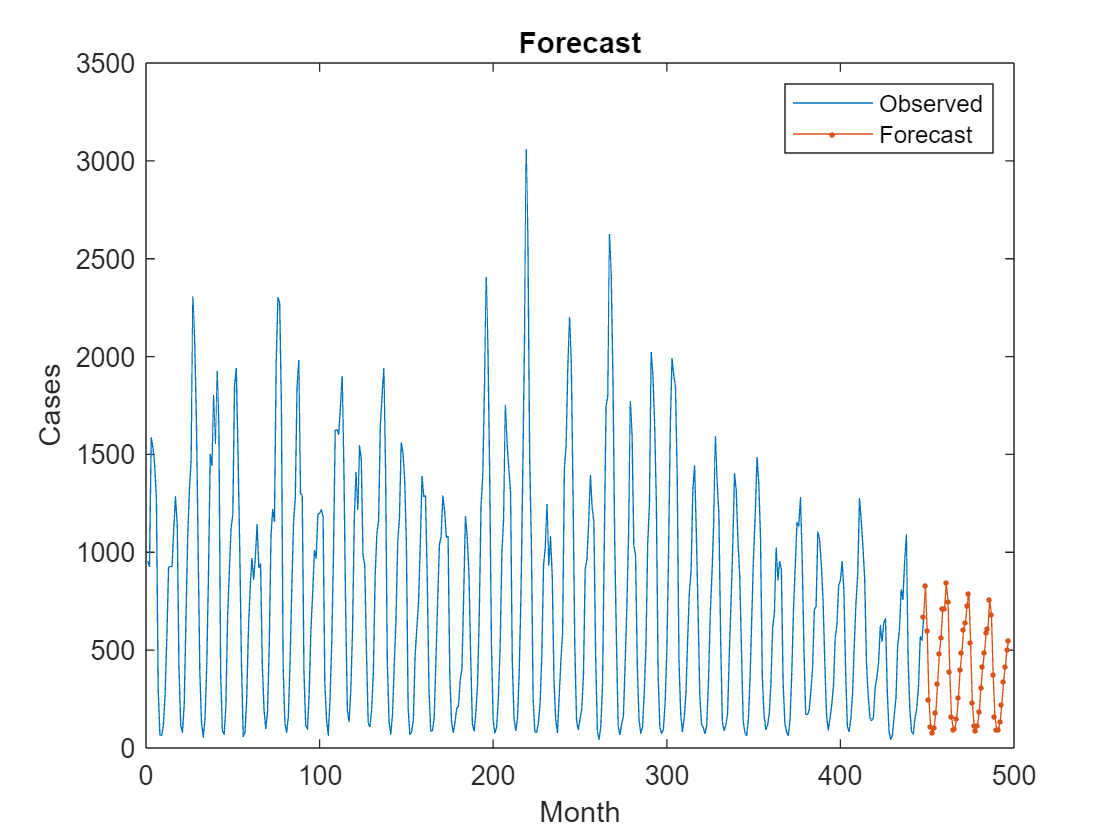

figure
plot(data(1:numTimeStepsTrain))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

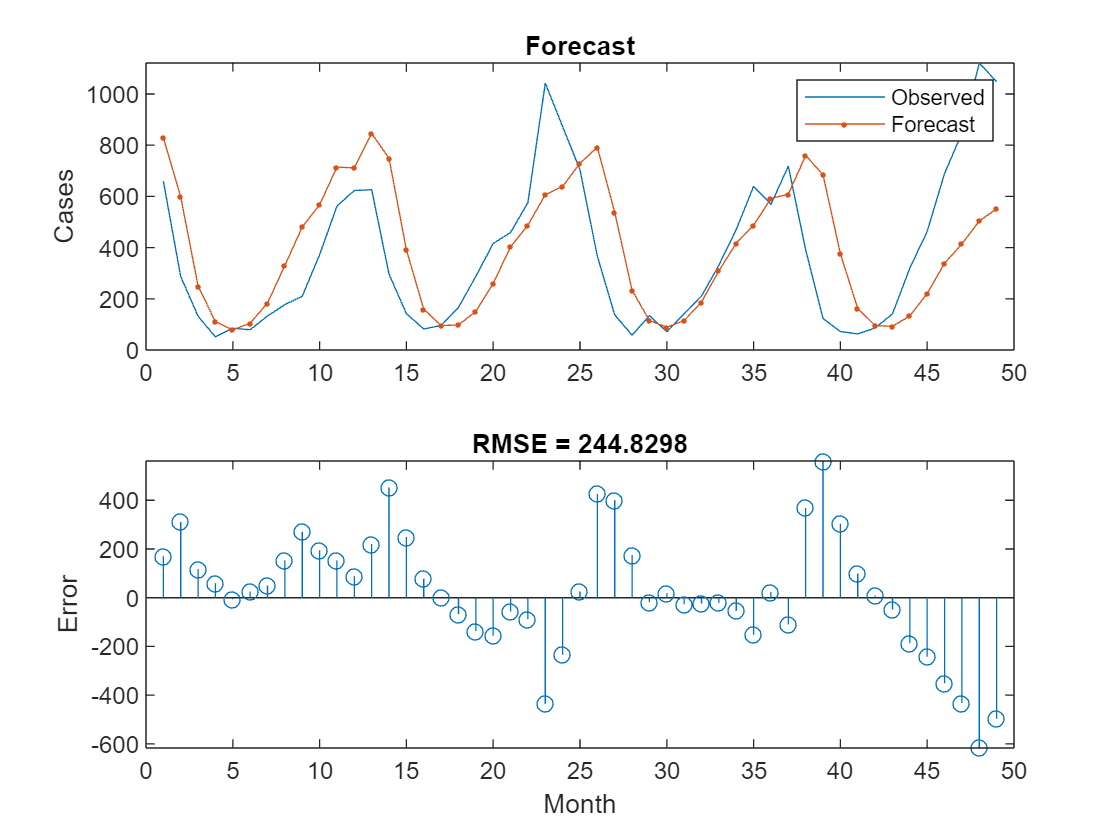


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

## 9.4 案例2：基于LSTM的人体活动动作识别

- **导入训练集数据，并可视化**

        数据文件HumanActivityTrain.mat中包括了变量XTrain和YTrain，均为6*1的元胞数组，XTrain的每个元胞数组中存储了智能手机内置的加速度传感器在一段时间内记录的数据，一共三行，分别对应X，Y，Z三轴的加速度。YTrain的每个元胞数组中存储了与之对应的每个时刻点的动作类别，一共包括5类：Sitting、Standing、Walking、Running、Dancing。

load HumanActivityTrain
XTrain

XTrain = 6×1 cell array
    {3×64480 double}
    {3×53696 double}
    {3×56416 double}
    {3×50688 double}
    {3×51888 double}
    {3×54256 double}


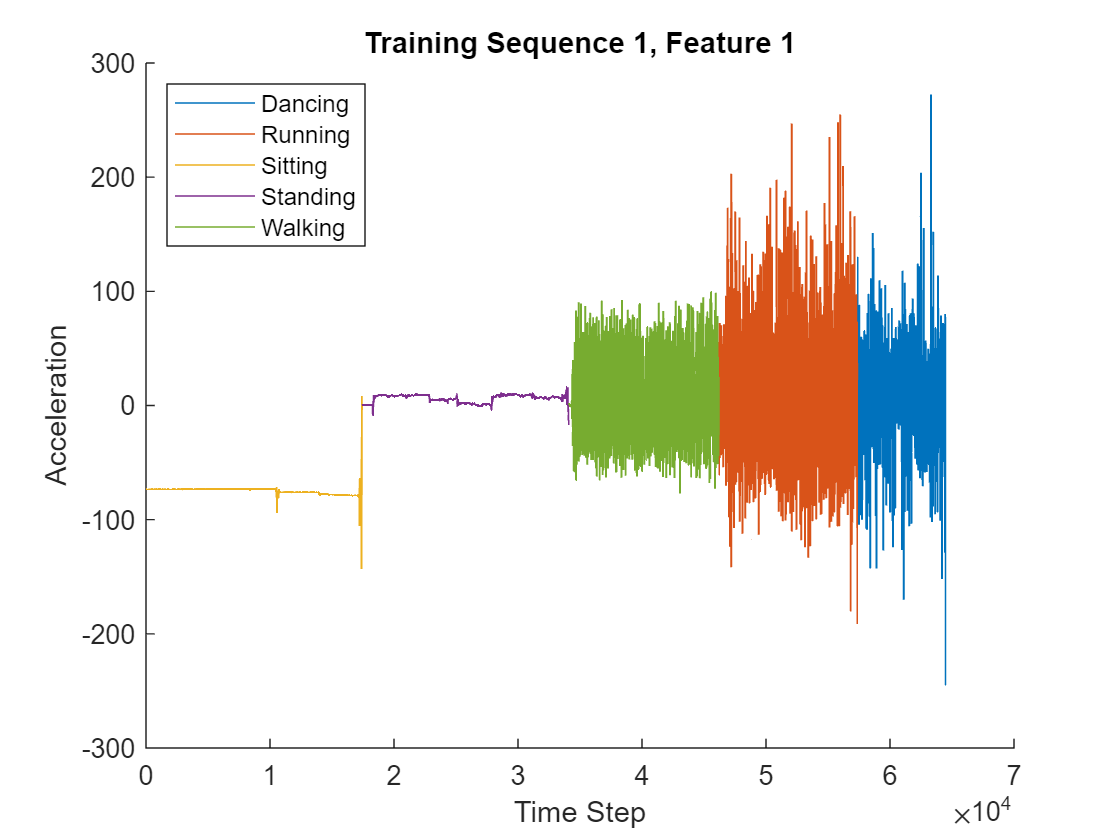


% 数据可视化
X = XTrain{1}(1,:);
classes = categories(YTrain{1});

figure
for j = 1:numel(classes)
    label = classes(j);
    idx = find(YTrain{1} == label);
    hold on
    plot(idx,X(idx))
end
hold off

xlabel("Time Step")
ylabel("Acceleration")
title("Training Sequence 1, Feature 1")
legend(classes,'Location','northwest')

- **定义LSTM神经网络拓扑结构**

numFeatures = 3;
numHiddenUnits = 200;
numClasses = 5;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

- **设置训练参数**

options = trainingOptions('adam', ...
    'MaxEpochs',60, ...
    'GradientThreshold',2, ...
    'Verbose',0, ...
    'Plots','training-progress');

- ** 训练LSTM神经网络模型**

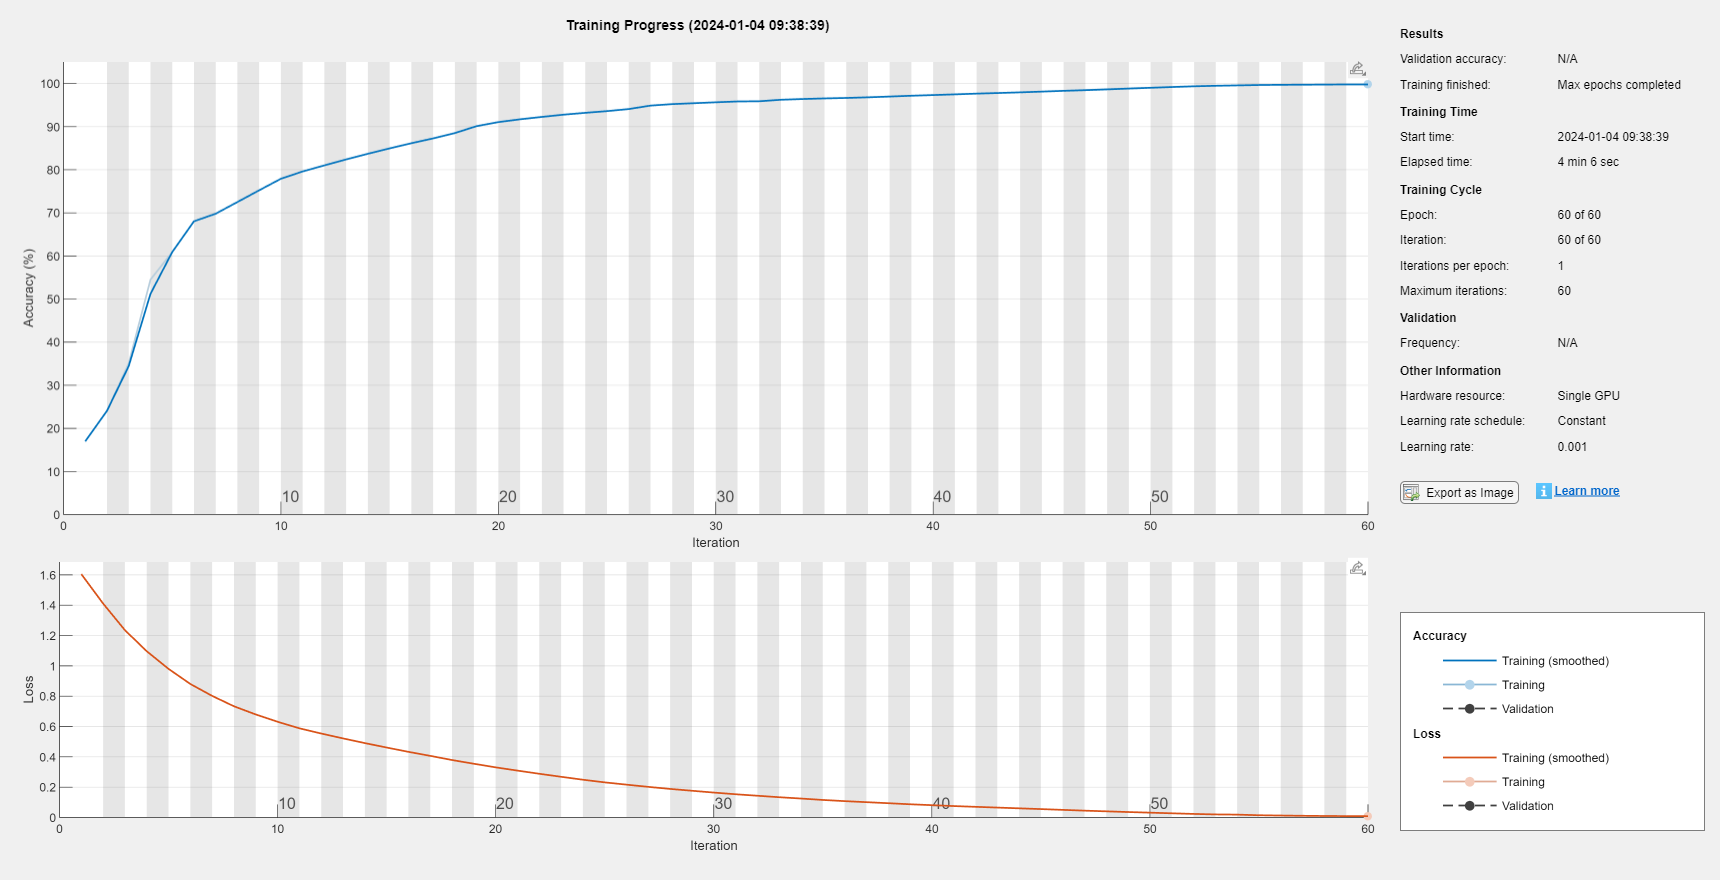

net = trainNetwork(XTrain,YTrain,layers,options);

- **导入测试集数据**

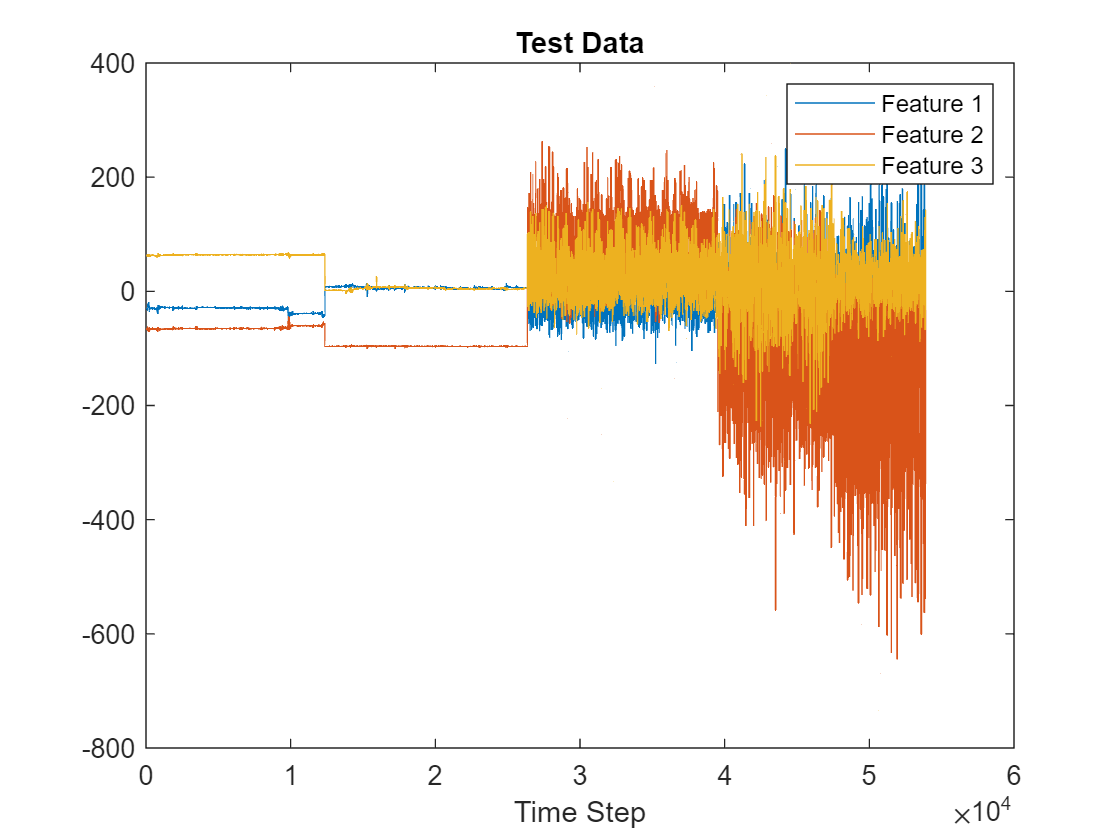

load HumanActivityTest
figure
plot(XTest{1}')
xlabel("Time Step")
legend("Feature " + (1:numFeatures))
title("Test Data")

- ** LSTM神经网络模型预测**

YPred = classify(net,XTest{1});

- **  计算预测准确率**

acc = sum(YPred == YTest{1})./numel(YTest{1})

acc = 0.9998

- **  结果绘图展示**

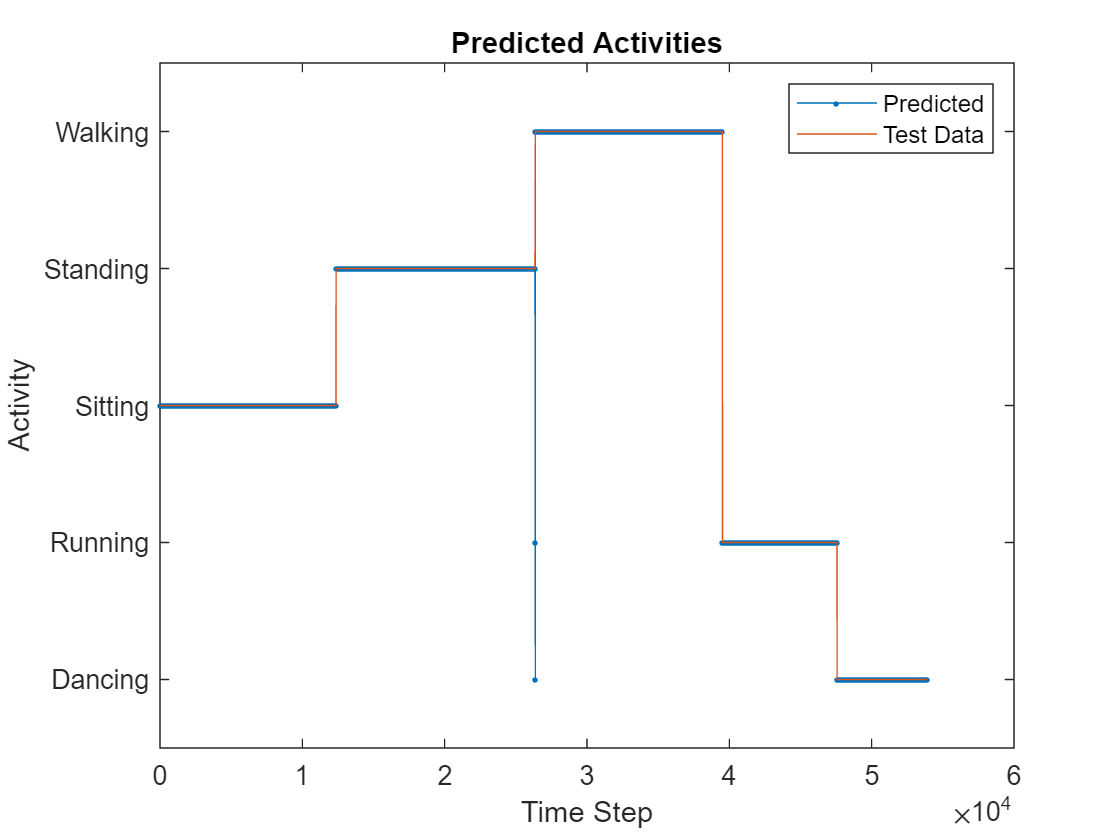

figure
plot(YPred,'.-')
hold on
plot(YTest{1})
hold off

xlabel("Time Step")
ylabel("Activity")
title("Predicted Activities")
legend(["Predicted" "Test Data"])